clear all
clf
format shortg

% data = xlsread("Statestik\Eksamens sæt\22F\Data_M4STI1_2022F.xlsx");
% data_size = size(data)

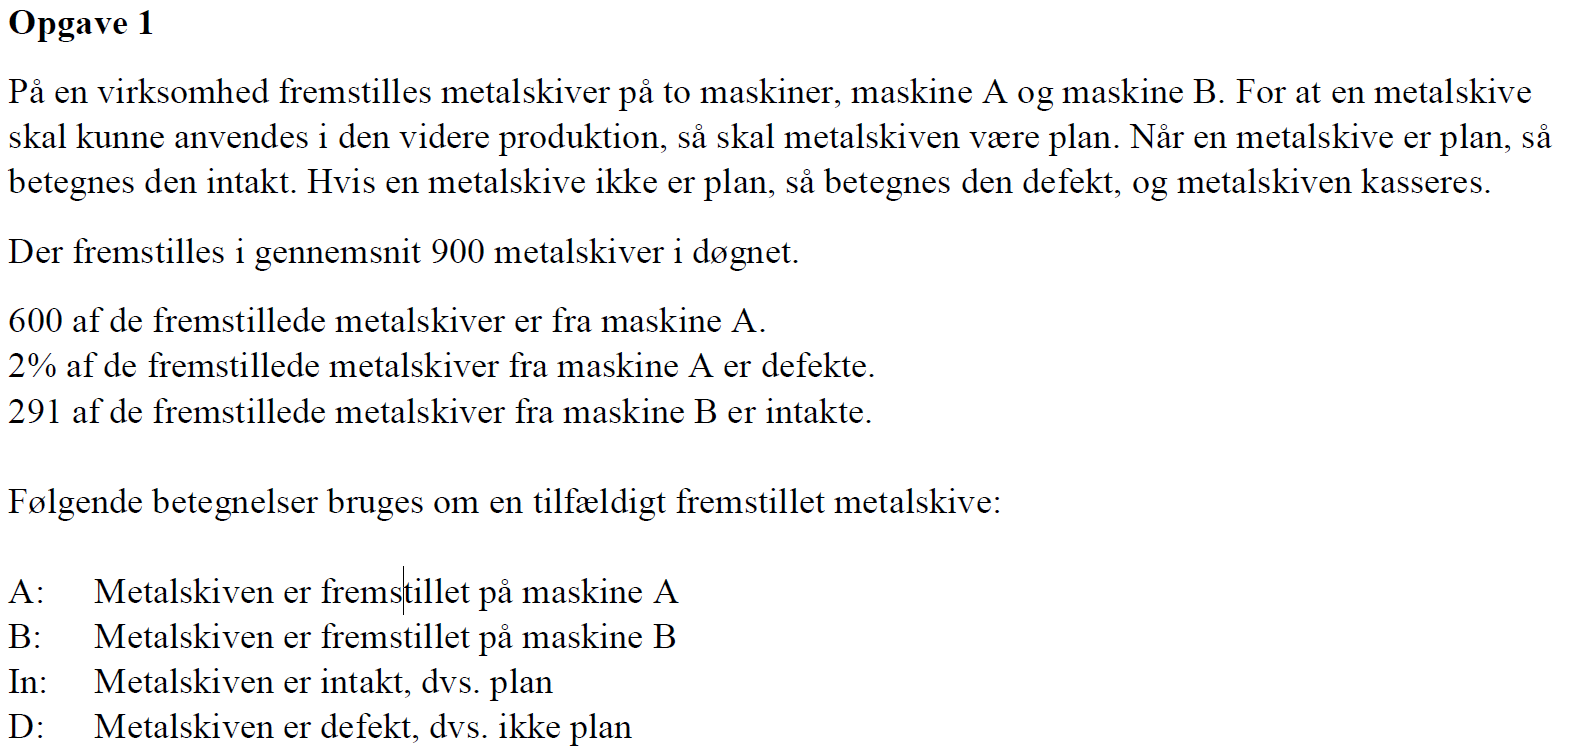

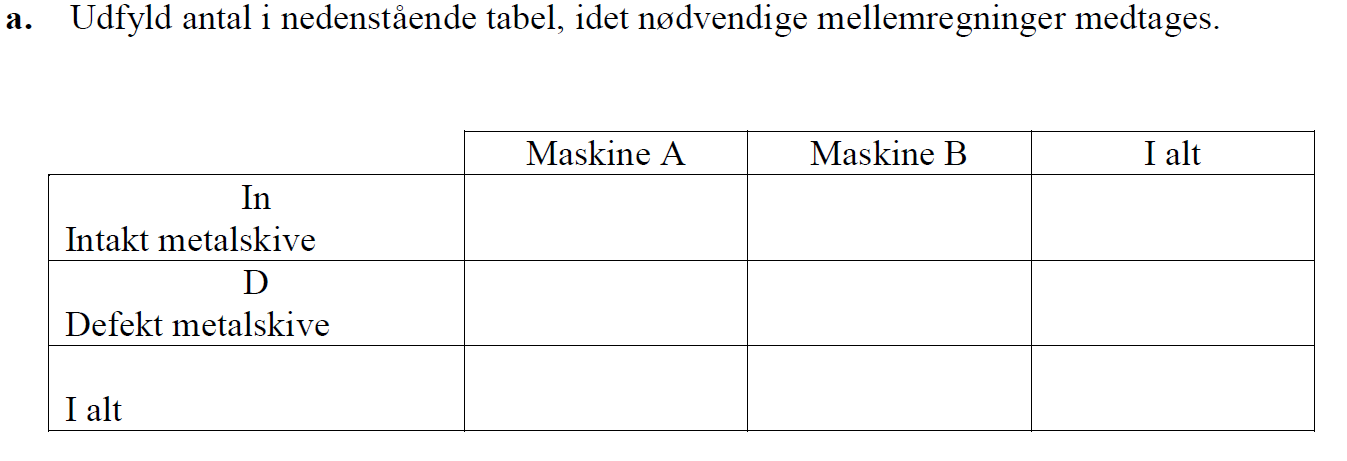

tot = 900

tot =    900


A_tot = 600

A_tot =    600


A_def = 0.02*A_tot

A_def =     12


A_in = A_tot - A_def 

A_in =    588


B_tot = 300

B_tot =    300


B_in = 291

B_in =    291


B_def = 9

B_def =      9


def_tot = A_def + B_def

def_tot =     21


int_tot = A_in + B_in

int_tot =    879


Kol_names = {'Maskine A', ' Maskine B', 'I alt'};
row_names = {'In - intakt metalskive', 'D - defekt metalskive', 'I alt'};
table([A_in; A_def; A_tot], [B_in; B_def; B_tot], [int_tot; def_tot; tot], VariableNames=Kol_names, RowNames=row_names)

ans = 3×3 table
                              Maskine A     Maskine B    I alt
                              _________    __________    _____

    In - intakt metalskive       588          291         879 
    D - defekt metalskive         12            9          21 
    I alt                        600          300         900 


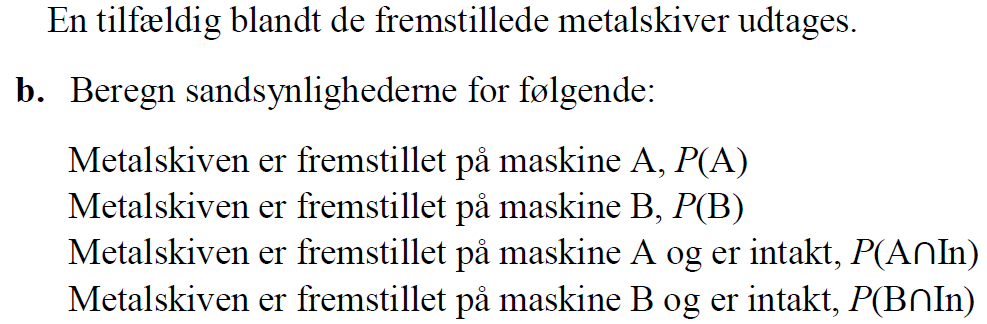

P_A = A_tot / tot

P_A =       0.66667


P_B = B_tot / tot

P_B =       0.33333


P_A_fel_in = A_in/tot

P_A_fel_in =       0.65333


P_B_fel_in = B_in/tot

P_B_fel_in =       0.32333


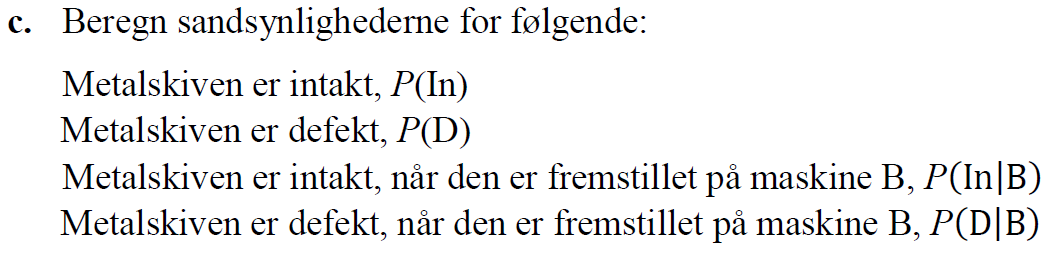

P_in = int_tot / tot

P_in =       0.97667


P_def = def_tot / tot

P_def =      0.023333


P_in_af_B = B_in / B_tot

P_in_af_B =          0.97


P_def_af_B = B_def / B_tot

P_def_af_B =          0.03


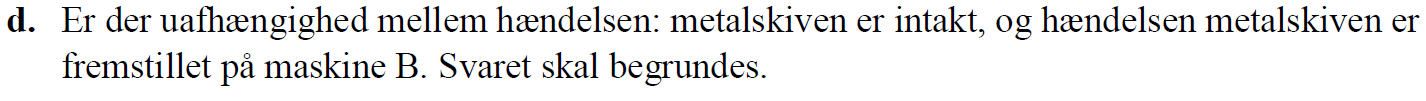

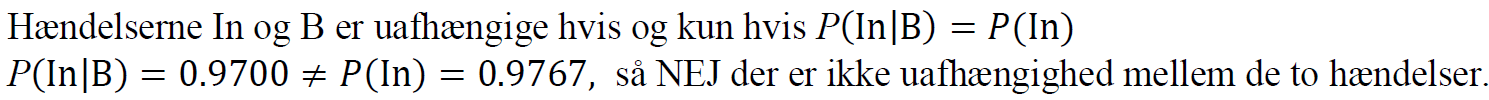

Der skal være lige stor sandsynlighed for at trække en intakt fra den totale pulje som for at trække en intakt fra puljen B - multiplikative lov

P_in_af_B 

P_in_af_B =          0.97


P_in

P_in =       0.97667


P_in_af_B == P_in

ans = logical
   0


Sandsynligheden er ikke ens og de er derfor ikke uafhængie

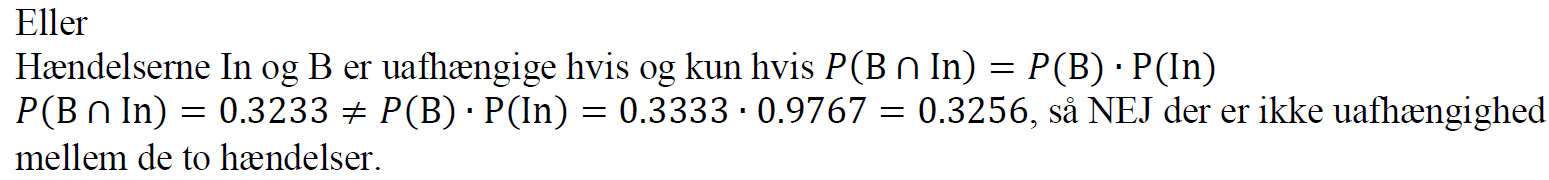

clear all
clf

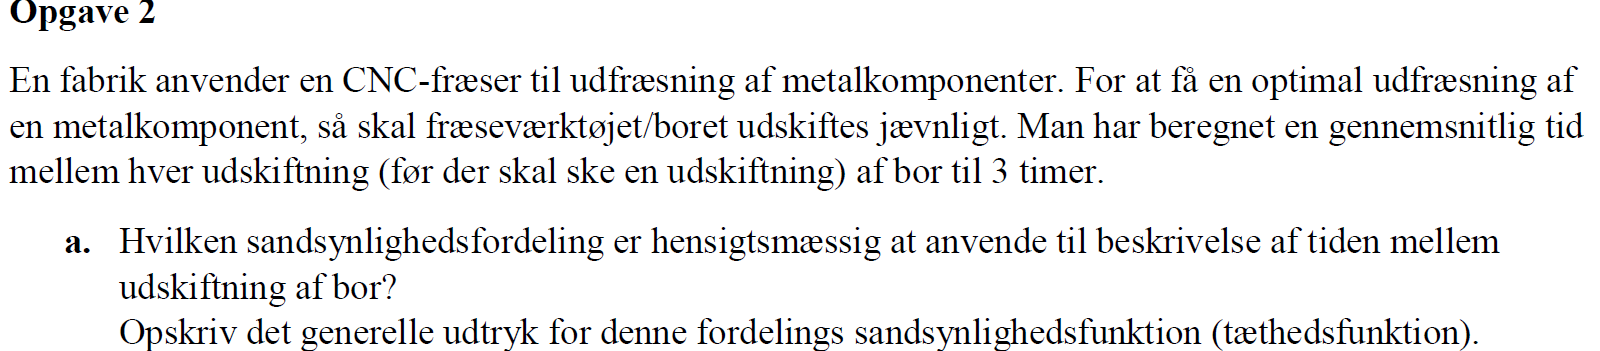

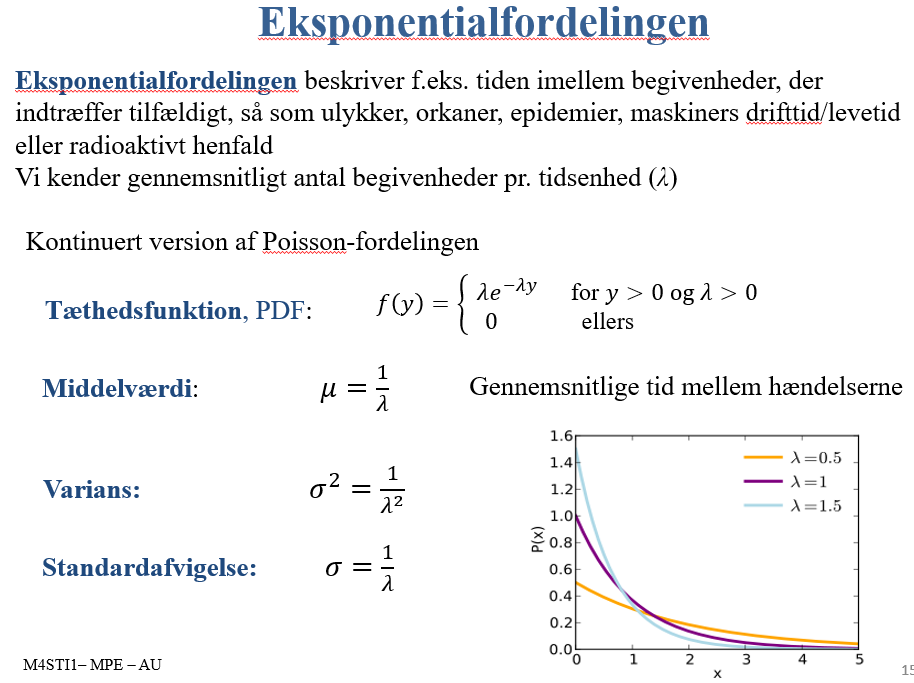

syms lambda y f(t)
f(t) = lambda * exp(-lambda * y)

$$f(t) = \lambda \,{\mathrm{e}}^{-\lambda \,y}$$

Som gælder for $y>0$ og $\lambda > 0$

b. Bestem det gennemsnitlige antal udskiftning af bor pr. time.

mu = 3 %timer

mu =      3


lambda = 1/mu

lambda =       0.33333


c. Bestem fordelingens middelværdi, varians og standardafvigelse.

mu

mu =      3


varians = 1/lambda^2

varians =      9


sigma = 1/lambda

sigma =      3


d. Bestem sandsynligheden for at boret skal udskiftes, inden for de første 2 timers brug.

y = 2; %timer
P_2 = expcdf(y,mu)

P_2 =       0.48658


Sandsyndligheden for skift af bor er således 48,7%

e. Bestem sandsynligheden for at der går mere end 6 timer før boret skal udskiftes.

y = 6; %timer
P_6 = 1 - expcdf(y,mu)

P_6 =       0.13534


Sandsynligheden er for at der går mere end 6 timer er således 13,5%

f. Bestem sandsynligheden for at der går mellem 2 og 4 timer før boret skal udskiftes.

y = 4; %timer
P_4 = expcdf(y,mu);
P_24 = P_4 - P_2

P_24 =       0.24982


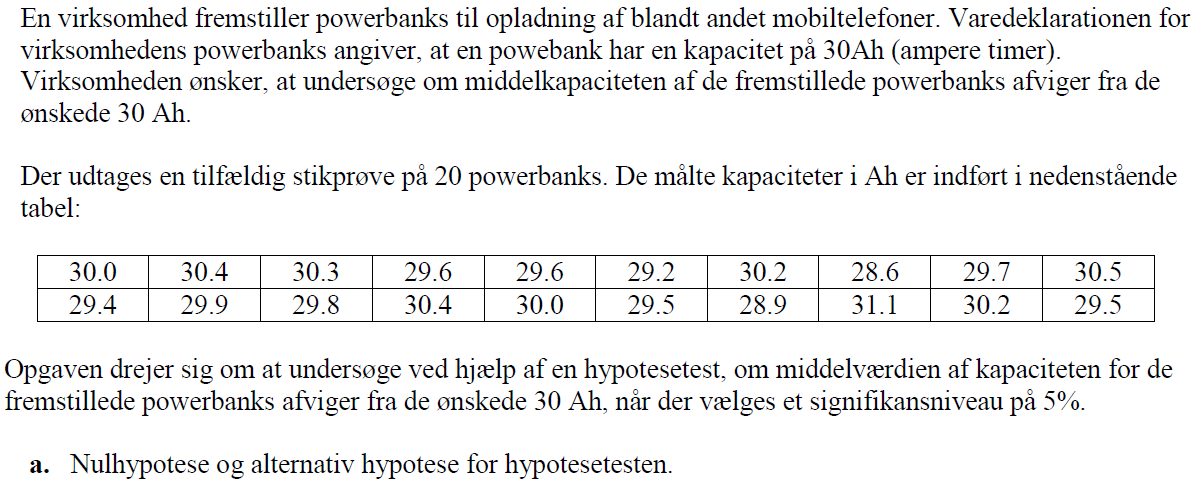

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\22F\Data_M4STI1_2022F.xlsx");
kap = data(:,1);

mu_0 = 30

mu_0 =     30


s = std(kap)

s =       0.58795


mu = mean(kap)

mu =         29.84


n = length(kap)

n =     20


df = n -1

df =     19


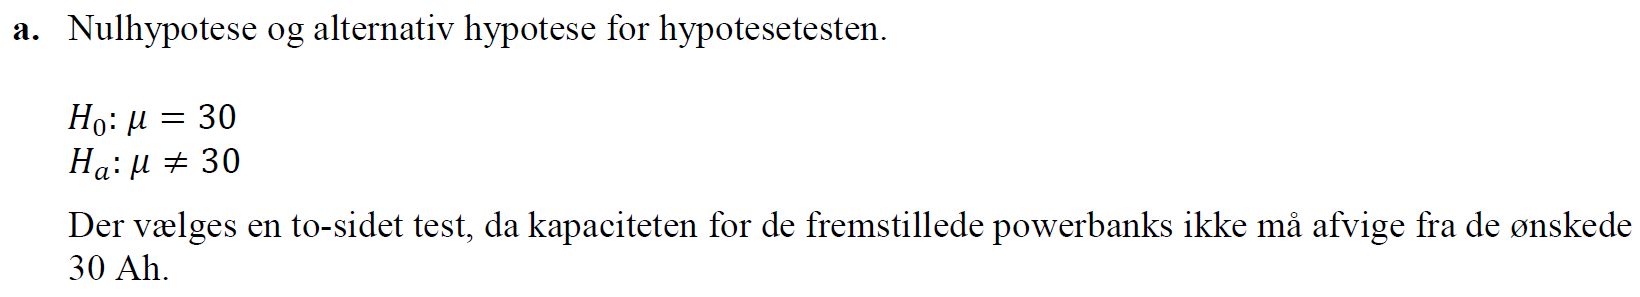

b. Opstil en formel for teststørrelsen (teststatistikken), og angiv hvilken fordeling den følger.

der vægles test 2 med en t fordeling

t_0 = (mu - mu_0) / (s / sqrt(n))

t_0 =        -1.217


% t_0 * s/sqrt(n)

c. Bestem det kritiske område for testen.

t_c = tinv(1-0.025,df)

t_c =         2.093


d. Beregn teststørrelsens (teststatistikkens) værdi, idet nødvendige mellemregninger medtages.

t_0 = (mu - mu_0) / (s / sqrt(n))

t_0 =        -1.217


STAT.t_student(kap, s, mu_0)

ans =        -1.217


e. Konkluder på hypotesetesten.

t_0

t_0 =        -1.217


t_c

t_c =         2.093


abs(t_0) < t_c

ans = logical
   1


teststørrelsens er dermed ikke ude i det kritiske område af og vores hypotese kan fastholdes

$H_0$** kan ikke forkastes**

f. Hvilke antagelser er der foretaget for at udføre hypotesetesten?

Er disse antagelser rimelige? Vurderingen af data skal foregå på baggrund af normalfordelingsplot og f.eks. stem-and-leaf-plot

Det er antaget at populationen er normalfordelt og at vores stikprøve er t-fordelt, da det antages at den centralegrænseværdisætning gælder.

normplot(kap)

På normal plottet ses også en fin ret linje hvilket viser et fint sammenhæng

stemleafplot(kap,-1)

  28 | 6 9
  29 | 2 4 5 5 6 6 7 8 9
  30 | 0 0 2 2 3 4 4 5
  31 | 1
key: 36|5 = 36.5
stem unit: 1.0
leaf unit: 0.1


I stem and leaf plottet ses også en find normalfordeling

andet svar her:

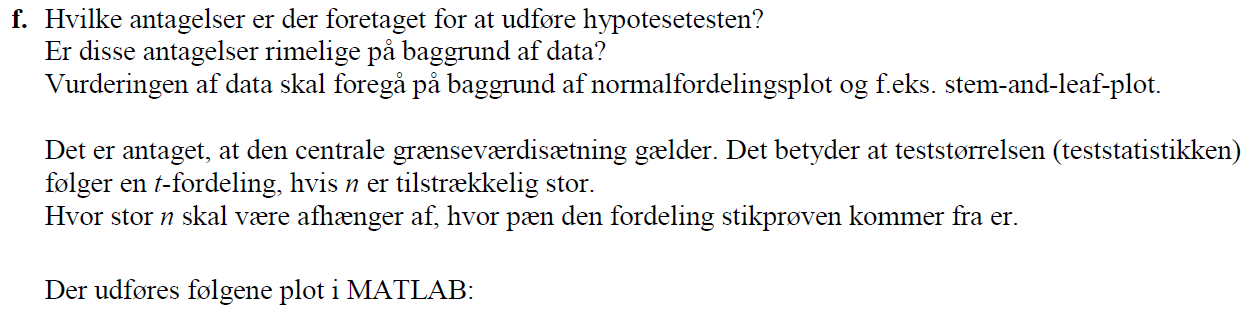

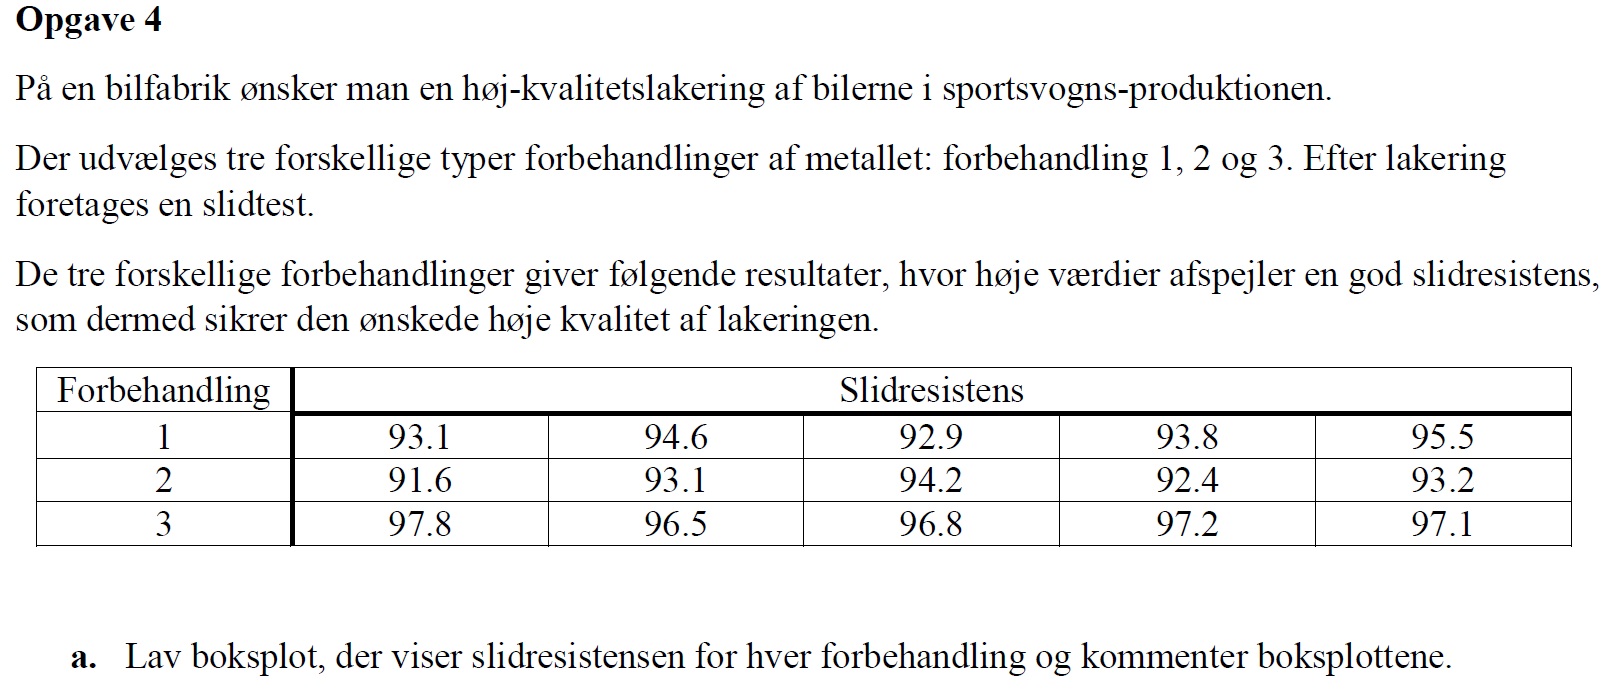

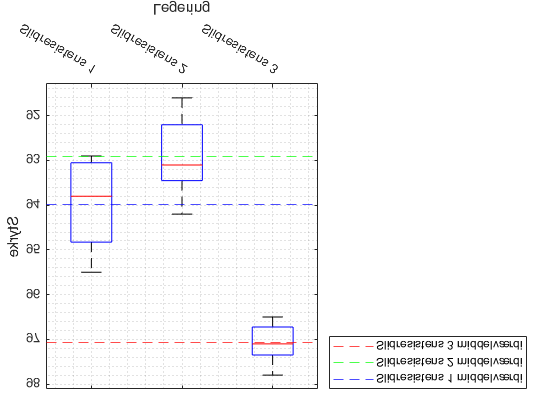

clear all
clf

data = xlsread('Data_M4STI1_2022F.xlsx');

%rækker
n_start = 1; %første række af datapunkter
n_slut = 15; % sidste rækker af data
n_treat = 5; % antal data per forsøg

%kollonner
col = 6; % collonnen dataen er i
treatment = 5; % hvilket forsøg dataen tilhøre (fx kolonnen med tilhørende tal 111 222 333)

labels = {'Slidresistens 1', 'Slidresistens 2', 'Slidresistens 3'};


boxplot(data(n_start:n_slut, col),data(n_start:n_slut, treatment), ... % 'Orientation','horizontal',
         "Labels", labels)
colors = {'--b', '--g', '--r'};

for i = n_start:n_slut/n_treat
    yline(mean(data(n_start:n_start + n_treat - 1, col)), string(colors(i)), 'DisplayName', string(labels(i)) + ' middelværdi')
    n_start = n_start + n_treat;
end

ylabel('Styrke')
xlabel('Legering')
legend('location', 'northeastoutside')
grid("minor")

b. Denne delopgave drejer sig om at undersøge ved hjælp af en variansanalyse, om der er en forskellig effekt af forbehandlingerne på slidresistensen, dvs. om der er forskel på middelværdierne af slidresistensen for de tre forbehandlinger. Der vælges et signifikansniveau på 5%.

1. Opstil nulhypotese og alternativ hypotese for variansanalysen.

VI opstiller 0 hypotese

$H_0$: $\mu_{tot} = \mu_1 = \mu_2 = \mu_3$

$H_a$: $\mu_{tot} \neq \mu_1 \neq \mu_2 \neq \mu_3$

eller

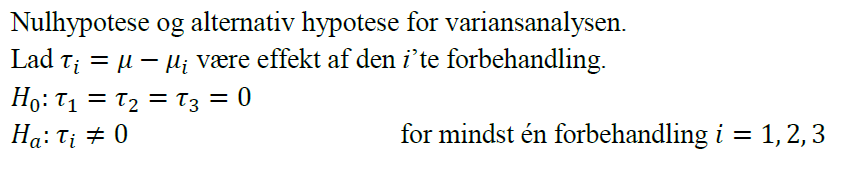

slidres = data(1:15, 6);
mean(slidres)

ans =        94.653


slidres1 = data(1:5, 6);
slidres2 = data(6:10, 6);
slidres3 = data(11:15, 6);
forbehand = data(1:15, 5);
% mean(slidres1)
% mean(slidres2)
% mean(slidres3)

2. Formuler nulhypotese og alternativ hypotese med ord.

Hvis alle slidstyrker skal være ens skal deres middel værdi være ens med den totale middel værdi

3. Udfør variansanalysen f.eks. med anovan.


mdl = fitlm([slidres1; slidres2; slidres3], forbehand)%[forbehand(1:5); forbehand(6:10), forbehand(11:15)])

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    -23.986      8.3758    -2.8638       0.0133
    x1             0.27454     0.08847     3.1032    0.0083944


Number of observations: 15, Error degrees of freedom: 13
Root Mean Squared Error: 0.665
R-squared: 0.426,  Adjusted R-Squared: 0.381
F-statistic vs. constant model: 9.63, p-value = 0.00839

figure(1)
plot(mdl)

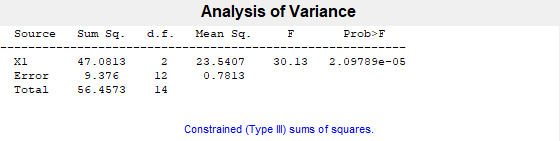

ans =    2.0979e-05


% mdl = fitlm(slidres, forbehand)
% [p, table, stats] = anova(slidres, forbehand)
% anova_sti(mdl)
anovan(slidres, forbehand)

anova_sti(mdl)

 
ANOVA_STI:
                  SumSq     DF      MeanSq          F           pValue  
                  ______    __    __________    __________    __________

    Regression    4.2554     1        4.2554        9.6301     0.0083944
    Residual      5.7446    13       0.44189                            
    Total             10    14                                          



% [yhat,yci] = predict(mdl,x)
% [yhat,ypi]=predict(mdl,x,'Prediction','observation')

4. Konkluder på variansanalysen.

Vores P værdi er mindre end vores signifikansniveauet på 0.05 derved forkastes $H_0$ hypotese og $H_a$ accepteres.

Dvs. at mindst en af forbehandlingerne har en effekt på slidresistensen.

5. Hvilke antagelser skal være opfyldt for residualerne ved variansanalysen?